We repeat the earlier process to blur the original image $\mathbf{X}$ to get $\mathbf{Z}$. 

load mandrill
[m,n] = size(X)

m =    480


n =    500


v = [1/4 1/2 1/4];
B = spdiags( repmat(v,m,1), -1:1, m,m);
C = spdiags( repmat(v,n,1), -1:1, n,n);
blur = @(X) B^12 * X * C^12;
Z = blur(X);

Now we imagine that $\mathbf{X}$ is unknown and that the blurred $\mathbf{Z}$ is given. We want to invert the blur transformation using the transformation itself. But we have to translate between vectors and images each time. 

vec = @(X) reshape(X,m*n,1);
unvec = @(x) reshape(x,m,n);
T = @(x) vec( blur(unvec(x)) );

Now we apply `gmres` to the composite blurring transformation `T`.

y = gmres(T,vec(Z),50,1e-5);

gmres(50) converged at outer iteration 2 (inner iteration 45) to a solution with relative residual 1e-05.


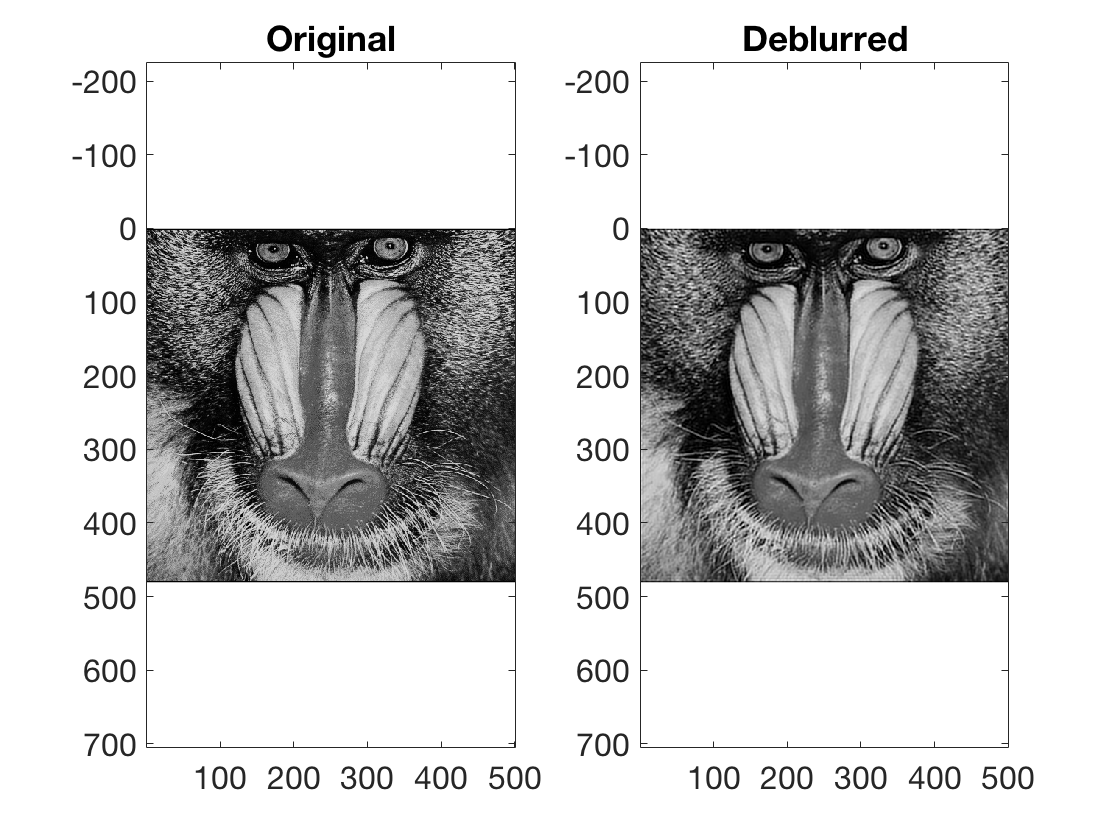

Y = unvec(y);

subplot(121)
image(X), colormap(gray(256))
axis equal, title('Original')    % ignore this line
subplot(122)
image(Y), colormap(gray(256))
axis equal, title('Deblurred')    % ignore this line

The reconstruction isn't perfect because the condition number of repeated blurring happens to be very large. 